# Subcortical Data Analysis

Below we will show you how to load the data aquired from Thalamus into matlab and generate Figure 5.

## Loading Variables

Contains information for the trial start and end times after excluding outlier trials. Obtained from the HDF5 file under the /events/data and /events/recieved. Also contains movement start and end times determined by thresholding the velocity.

f = load('filtEvents.mat')

Contains information for the trial start and end times as well as the time axis for the kinematics and subcortical data aquired directly from the HDF5 file.  Kinematic time can be found under /xsens/handengine/recieved. Subcortical data time can be found under /analog/alphaomega/LFP 01/recieved

load('Events.mat')

Position values obtained from the HDF5 file under /xsens/handengine/data

load('Position.mat')

Contains the velocity averaged across all the hand (h) and body (b) sensors which was computed from the raw position values. bs and hs contain the speed (computed as Euclidean norm) accross x, y, and z directions

load('Velocity.mat')

Voltage STN data for 6 channels obtained from the HDF5 file under /analog/alphaomega/LFP ch#/data

load('AlphaOmegaData.mat')

Voltage STN data after Notch filtering 60Hz

load('AlphaOmegaNotch.mat')

Contains the STN data for 6 channels after computing power using Multitaper method and meaning over all freq in beta (13-35Hz)

load('AlphaOmegaBeta.mat')

Time axis for STN data following the Multitaper method

load('AlphaOmegaPSDtime.mat')

## Voltage Over Trial 10 in The STN

[AlphaOmegaLFP_EventPotentials,time,~]= EventRelatedPotentials(Events.alphaOmegaLfpTime,AlphaOmega.LFP,f.Events.movementBounds(:,1),[-2,2]);

Sampling rate: 1374.9971


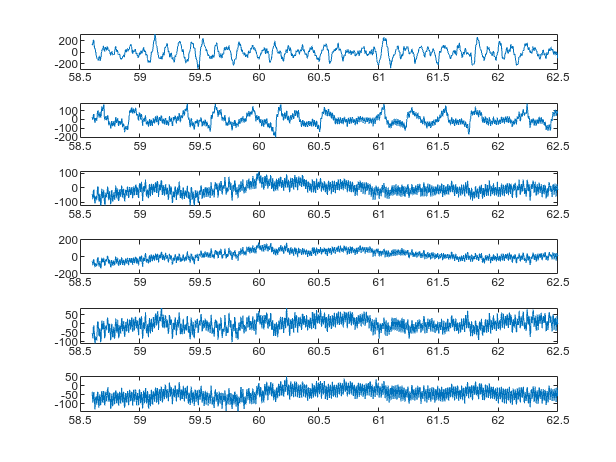

m=squeeze(AlphaOmegaLFP_EventPotentials(10,:,:));

fig = figure('Color', 'white');
tiledlayout(6, 1);
for i = 1:6
    nexttile;
    plot(sq(time(10,:)), m(i,:));
    xlim([58.5,62.5])
end

## Computing Beta Power Over Trial 10

[AlphaOmegaLFP_EventPotentialsBeta,time,~]= EventRelatedPotentials(PSDtime,AlphaOmegaBeta,f.Events.movementBounds(:,1),[-2,2]);

Sampling rate: 4.9972


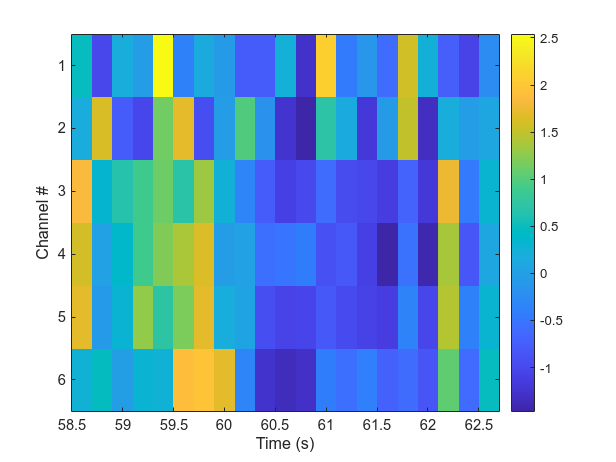

m=sq(AlphaOmegaLFP_EventPotentialsBeta(10,:,:));
mz=zscore(m,0,2);

figure('Color','w')
imagesc(sq(time(10,:)),[],mz)
xlabel('Time (s)')
ylabel('Channel #')
colorbar;

## Computing Velocity of The Hand Over Trial 10

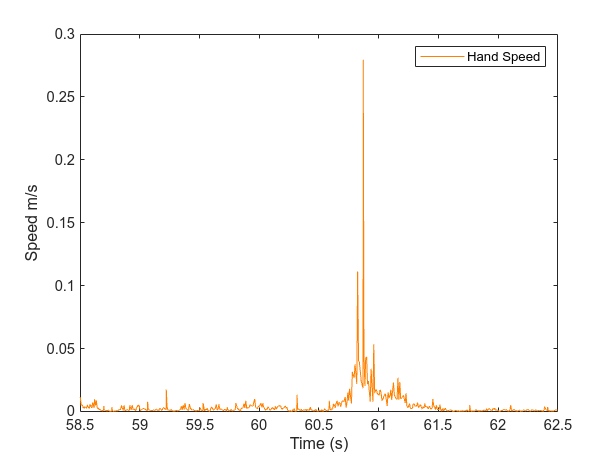

figure('Color','w');
plot(Events.kinematicTimesHand(2:end), V.hs,'Color', [1, 0.5, 0]);
hold on
xlim([58.5,62.5])
xlabel('Time (s)')
ylabel('Speed m/s')
legend({'Hand Speed'})
hold off

## Computing Power Spectra for All Movements Versus Baseline

[PSD, F, timeAxis] = ComputePSD(AlphaOmegaNotch.LFP, Events.alphaOmegaLfpTime, 1375, 0.8, 6.25); 

averagedPSDMovement = averagePSDAcrossIntervals(PSD, Events.movementBounds, timeAxis);

#### Loading Data for Baseline and Computing Power

load('Baseline_Events.mat') % STN time axis for baseline
load('Baseline_AlphaOmegaNotch.mat') % STN data Notch filtered for baseline
[PSD_Baseline, ~, ~] = ComputePSD(AlphaOmegaNotch.LFP, Events.alphaOmegaLfpTime, 1375, 0.8, 6.25);

averagedPSDBaseline = mean(PSD_Baseline,3);

#### Plotting

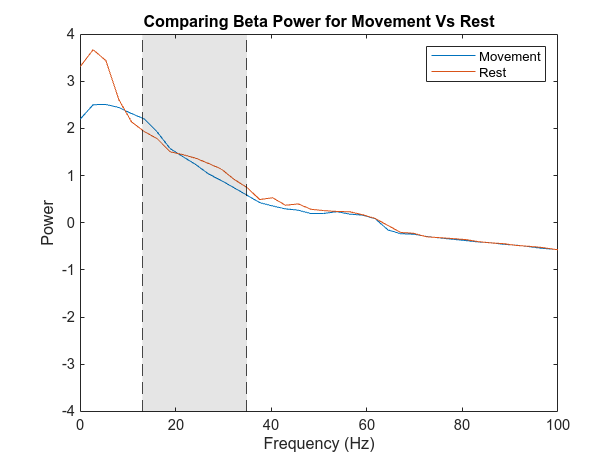

figure('Color', 'white');
plot(F, log10(squeeze(mean(averagedPSDMovement(1:5,:),1))));
hold on;
plot(F, log10(squeeze(mean(averagedPSDBaseline,1))));

start = 13;
stop = 34.91;
xline(start, '--k');
xline(stop, '--k'); 

x = [start stop stop start]; 
y = ylim; 
fill(x, [y(1) y(1) y(2) y(2)], 'k', 'FaceAlpha', 0.1, 'EdgeColor', 'none');

xlabel('Frequency (Hz)');
ylabel('Power');
xlim([0,100])
title('Comparing Beta Power for Movement Vs Rest');
legend('Movement', 'Rest');
hold off;

## Computing Power Difference in Beta STN Across Patients

Note: Patient 1 has no baseline recording so will use pre-cue period as baseline

### Load Events and AlphaOmegaData. Variables extracted are called Events and AlphaOmega

load('AlphaOmegaData.mat')
load('Events.mat')
fieldsToCheck = {'RAW01','RAW02','RAW03','RAW04','RAW05','MacroRAW01'};
availableFields = fieldsToCheck(cellfun(@(f) isfield(AlphaOmega,f), fieldsToCheck));
nCh = numel(availableFields);

if nCh == 0
    warning('No RAW channels found in AlphaOmega.');
    alphaOmegaRAW = [];
    alphaOmega = [];
    alphaOmegaTime = [];
    return;
end

% 2. Preallocate and populate the raw data matrix (channels × time)
rawLength = numel(AlphaOmega.(availableFields{1}));
alphaOmegaRAW = zeros(nCh, rawLength);
for i = 1:nCh
    fld = availableFields{i};
    vec = AlphaOmega.(fld);
    alphaOmegaRAW(i, :) = vec(:)';
end

% 3. Compute original sampling rate from the Events time axis
t_raw = AlphaOmega.Times.RAW01;
dt_raw = median(diff(t_raw));
fs_raw = 1 / dt_raw;

% 4. Downsample data to 1000 Hz with anti-aliasing (Nyquist) filter
dsFactor = round(fs_raw / 1000);
alphaOmega = zeros(nCh, ceil(rawLength / dsFactor));
for i = 1:nCh
    alphaOmega(i, :) = decimate(alphaOmegaRAW(i, :), dsFactor);
end

% 5. Downsample the time axis to 1000 Hz (retain original offsets)
dsTimeFactor = round(fs_raw / 1000);
alphaOmegaTime = t_raw(1:dsTimeFactor:end);

Audio = Events.Sound/1e3;
[segData_AO,segTime_AO,normalizedTime_AO,samplingRate] =EventRelatedPotentials(alphaOmegaTime,alphaOmega,Events.movementBounds(:,1),[-.2,.8]);
[segData_AO_Baseline,segTime_AO_Baseline,normalizedTime_AO_Baseline] =EventRelatedPotentials(alphaOmegaTime,alphaOmega,Audio,[-1,0]);
segData_AO_Baseline(1,:,:)=[];          % delete 1st epoch
segTime_AO_Baseline(1,:) = [];         % delete corresponding time vector


time_resolution = 0.8;
freq_resolution = 6.25;

for i=1:size(segData_AO,1)
x=squeeze(segData_AO(i,:,:));
[PSD_AlphaOmega(i,:,:,:), F_AlphaOmega, AlphaOmega_PSD_Time] = ComputePSD(x, normalizedTime_AO, samplingRate, time_resolution, freq_resolution);  % PSD output is segments by channels by freq by time
end

for i=1:size(segData_AO_Baseline,1)
x=squeeze(segData_AO_Baseline(i,:,:));
[PSD_AlphaOmega_Baseline(i,:,:,:), ~, ~] = ComputePSD(x, normalizedTime_AO_Baseline, samplingRate, time_resolution, freq_resolution);  % PSD output is segments by channels by freq by time
end

PSD_AlphaOmega = squeeze(mean(PSD_AlphaOmega,4)); %Avg across time
PSD_AlphaOmega_Beta = PSD_AlphaOmega(:,2:6,14:37); % Isolate beta and good channels
PSD_AlphaOmega_Beta_1 = squeeze(mean(mean(PSD_AlphaOmega_Beta,3),2)); % Average across trials and across freq bins


PSD_AlphaOmega_Baseline = squeeze(mean(PSD_AlphaOmega_Baseline,4)); %Avg across time
PSD_AlphaOmega_Baseline = PSD_AlphaOmega_Baseline(:,2:6,14:37); % Isolate beta and good channels
PSD_AlphaOmega_Beta_Baseline_1 = squeeze(mean(mean(PSD_AlphaOmega_Baseline,3),2)); % Average across trials and across freq bins



## Patient 2

### Load patient2_AlphaOmegaData.mat, variable is 'Data'

load('patient2_AlphaOmegaData.mat') % STN time axis for baseline
time_resolution = 0.8;
freq_resolution = 6.25;


PSD_AlphaOmega_Beta_2 = squeeze(mean(Data.AlphaOmega_PSD,4)); %Avg across time
PSD_AlphaOmega_Beta_2 = PSD_AlphaOmega_Beta_2(:,4,14:37); % Isolate beta and good channels
PSD_AlphaOmega_Beta_2 = squeeze(mean(mean(PSD_AlphaOmega_Beta_2,3),2)); % Average across trials and across freq bins


PSD_AlphaOmega_Beta_Baseline_2 = squeeze(mean(Data.AlphaOmega_PSD_Baseline,4)); %Avg across time (trials by channels by freq by time)
PSD_AlphaOmega_Beta_Baseline_2 = PSD_AlphaOmega_Beta_Baseline_2(:,4,14:37); % Isolate beta and good channels 
PSD_AlphaOmega_Beta_Baseline_2 = squeeze(mean(mean(PSD_AlphaOmega_Beta_Baseline_2,3),2)); % Average across trials and across freq bins


## Patient 3

### Load patient3_AlphaOmegaData.mat, variable is 'Data'

load('patient3_AlphaOmegaData.mat')
time_resolution = 0.8;
freq_resolution = 6.25;


PSD_AlphaOmega_Beta_3 = squeeze(mean(Data.AlphaOmega_PSD,4)); %Avg across time
PSD_AlphaOmega_Beta_3 = PSD_AlphaOmega_Beta_3(:,2:6,14:37); % Isolate beta and good channels
PSD_AlphaOmega_Beta_3 = squeeze(mean(mean(PSD_AlphaOmega_Beta_3,3),2)); % Average across trials and across freq bins


PSD_AlphaOmega_Beta_Baseline_3 = squeeze(mean(Data.AlphaOmega_PSD_Baseline,4)); %Avg across time
PSD_AlphaOmega_Beta_Baseline_3 = PSD_AlphaOmega_Beta_Baseline_3(:,2:6,14:37); % Isolate beta and good channels
PSD_AlphaOmega_Beta_Baseline_3 = squeeze(mean(mean(PSD_AlphaOmega_Beta_Baseline_3,3),2)); % Average across trials and across freq bins

## Bar Plot

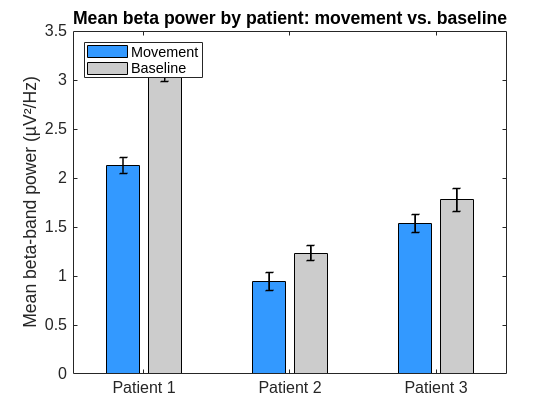

% Patient 1
meanMov(1)  = mean(PSD_AlphaOmega_Beta_1);
meanBase(1) = mean(PSD_AlphaOmega_Beta_Baseline_1);
semMov(1)   = std(PSD_AlphaOmega_Beta_1)  / sqrt(numel(PSD_AlphaOmega_Beta_1));
semBase(1)  = std(PSD_AlphaOmega_Beta_Baseline_1) / sqrt(numel(PSD_AlphaOmega_Beta_Baseline_1));

% Patient 2
meanMov(2)  = mean(PSD_AlphaOmega_Beta_2);
meanBase(2) = mean(PSD_AlphaOmega_Beta_Baseline_2);
semMov(2)   = std(PSD_AlphaOmega_Beta_2)  / sqrt(numel(PSD_AlphaOmega_Beta_2));
semBase(2)  = std(PSD_AlphaOmega_Beta_Baseline_2) / sqrt(numel(PSD_AlphaOmega_Beta_Baseline_2));

% Patient 3
meanMov(3)  = mean(PSD_AlphaOmega_Beta_3);
meanBase(3) = mean(PSD_AlphaOmega_Beta_Baseline_3);
semMov(3)   = std(PSD_AlphaOmega_Beta_3)  / sqrt(numel(PSD_AlphaOmega_Beta_3));
semBase(3)  = std(PSD_AlphaOmega_Beta_Baseline_3) / sqrt(numel(PSD_AlphaOmega_Beta_Baseline_3));

% rows = patients, columns = conditions (1 = Movement, 2 = Baseline)
means  = [ meanMov(:),  meanBase(:) ];    % 3×2
sems   = [  semMov(:),   semBase(:)  ];   % 3×2

figure('Color','w')
hb = bar(means, 'grouped');
hb(1).FaceColor = [0.2 0.6 1.0];  
hb(2).FaceColor = [0.8 0.8 0.8]; 
hold on

[numPatients, numConds] = size(means);   

groupwidth = min(0.8, numConds/(numConds+1.5));

for cond = 1:numConds
    x = (1:numPatients) ...
        - groupwidth/2 ...
        + (2*cond-1) * groupwidth/(2*numConds);

    errorbar( x,                     ... 
              means(:,cond),         ... 
              sems(:,cond),          ... 
              'k', 'linestyle','none', 'LineWidth',1.2 );
end


set(gca, ...
    'XTick', 1:3, ...
    'XTickLabel', {'Patient 1','Patient 2','Patient 3'}, ...
    'FontSize', 12 );
ylabel('Mean beta‐band power (µV²/Hz)')
legend({'Movement','Baseline'}, 'Location','NorthWest')
title('Mean beta power by patient: movement vs. baseline')

hold off